# Základní operace se signály

## Sčítání harmonických signálů

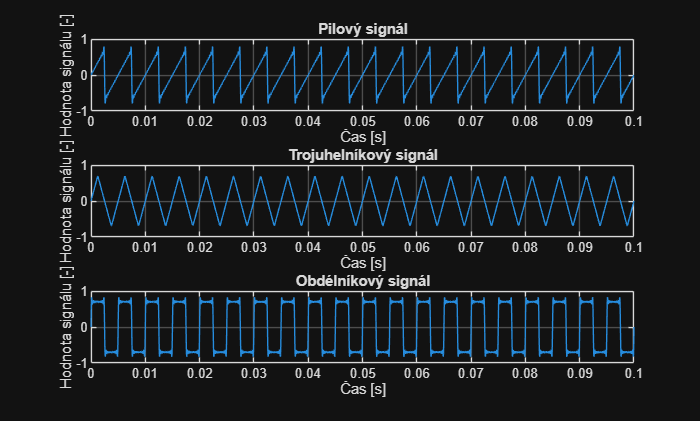

clc;
clear;
close all;

duration = 1;
fs = 96000;
f = 200;
num_harmonics = 10;
gain = 0.7;

[t, y_sawtooth] = oscillator(duration, fs, f, num_harmonics, gain, "sawtooth");
[~, y_triangle] = oscillator(duration, fs, f, num_harmonics, gain, "triangle");
[~, y_square] = oscillator(duration, fs, f, num_harmonics, gain, "square");

figure(1);

subplot(3, 1, 1);
plot(t, y_sawtooth);
title("Pilový signál");
xlabel("Čas [s]");
ylabel("Hodnota signálu [-]");
xlim([0, 0.1]);
ylim([-1, 1]);
grid on;

subplot(3, 1, 2);
plot(t, y_triangle);
title("Trojuhelníkový signál");
xlabel("Čas [s]");
ylabel("Hodnota signálu [-]");
xlim([0, 0.1]);
ylim([-1, 1]);
grid on;

subplot(3, 1, 3);
plot(t, y_square);
title("Obdélníkový signál");
xlabel("Čas [s]");
ylabel("Hodnota signálu [-]");
xlim([0, 0.1]);
ylim([-1, 1]);
grid on;

## Modulace signálu

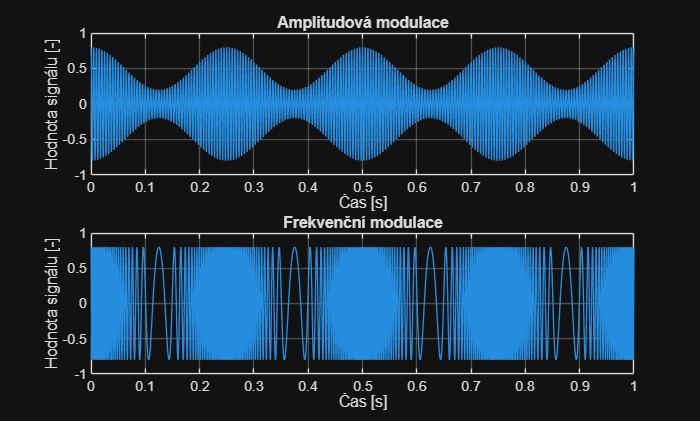

clc;
clear;
close all;

duration = 3;
fs = 48000;
fc = 200;
f_mod = 4;
f_dev = 180;
m = 0.6;
gain = 0.8;
type = "sine";
num_harmonics = 30;

[t, y_am] = am(duration, fs, fc, f_mod, m, gain, type, num_harmonics);
[~, y_fm] = fm(duration, fs, fc, f_mod, f_dev, gain);

figure(1);

subplot(2, 1, 1);
plot(t, y_am);
title("Amplitudová modulace");
xlabel("Čas [s]");
ylabel("Hodnota signálu [-]"); 
xlim([0, 1]);
ylim([-1, 1]);
grid on;

subplot(2, 1, 2);
plot(t, y_fm);
title("Frekvenční modulace");
xlabel("Čas [s]");
ylabel("Hodnota signálu [-]"); 
xlim([0, 1]);
ylim([-1, 1]);
grid on;


% sound(y_am, fs);

## Z-transformace / přenosová funkce

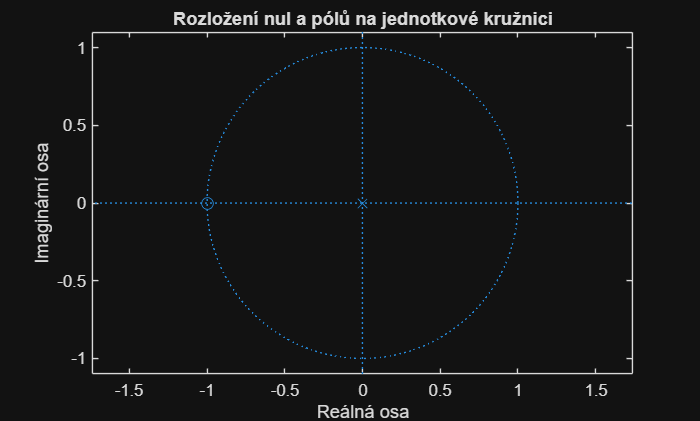

clc;
clear;
close all;

b = [0.5 0.5];
a = [1];

[z, p] = tf2zpk(b, a);

figure(1);

zplane(z, p);

title("Rozložení nul a pólů na jednotkové kružnici");
xlabel("Reálná osa");
ylabel("Imaginární osa");

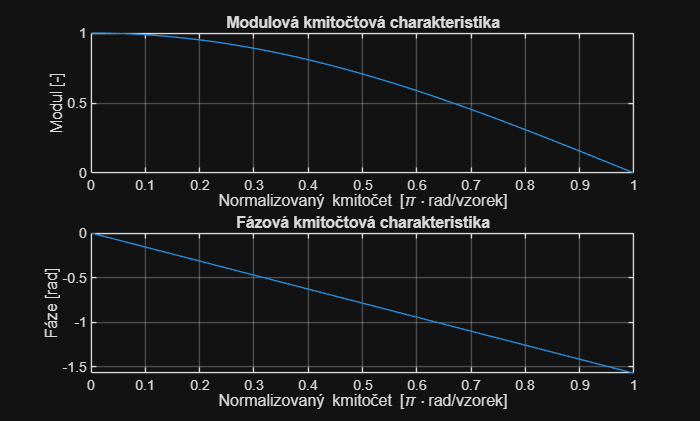


[H, w] = freqz(b, a);

H_mag = abs(H);
H_angle = angle(H);
f_norm = w / pi; 

figure(2);

subplot(2, 1, 1);
plot(f_norm, H_mag);
title("Modulová kmitočtová charakteristika");
xlabel("Normalizovaný kmitočet [\pi\cdotrad/vzorek]");
ylabel("Modul [-]");
grid on;

subplot(2, 1, 2);
plot(f_norm, H_angle);
title("Fázová kmitočtová charakteristika");
xlabel("Normalizovaný kmitočet [\pi\cdotrad/vzorek]");
ylabel("Fáze [rad]");
grid on;

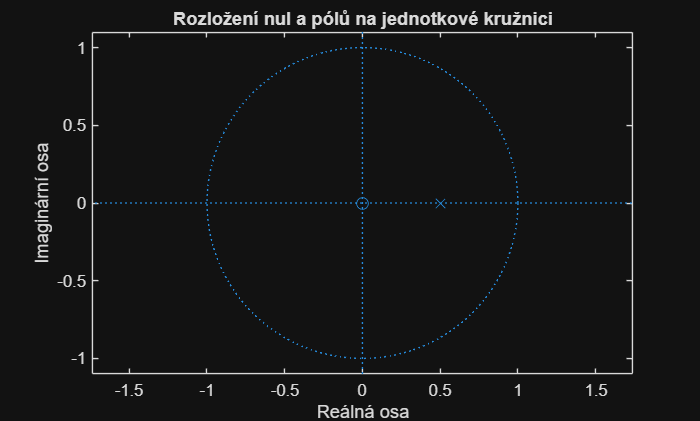

clc;
clear;
close all;

b = [0.5];
a = [1 -0.5];

[z, p] = tf2zpk(b, a);

figure(1);

zplane(z, p);

title("Rozložení nul a pólů na jednotkové kružnici");
xlabel("Reálná osa");
ylabel("Imaginární osa");

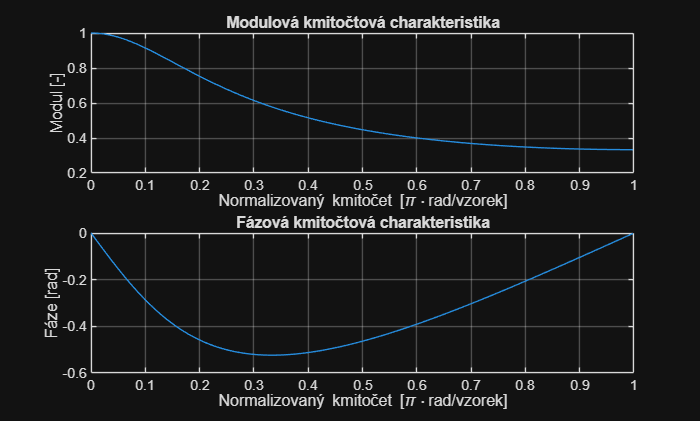


[H, w] = freqz(b, a);

H_mag = abs(H);
H_angle = angle(H);
f_norm = w / pi; 

figure(2);

subplot(2, 1, 1);
plot(f_norm, H_mag);
title("Modulová kmitočtová charakteristika");
xlabel("Normalizovaný kmitočet [\pi\cdotrad/vzorek]");
ylabel("Modul [-]");
grid on;

subplot(2, 1, 2);
plot(f_norm, H_angle);
title("Fázová kmitočtová charakteristika");
xlabel("Normalizovaný kmitočet [\pi\cdotrad/vzorek]");
ylabel("Fáze [rad]");
grid on;